%パラメータ設定
numNodes = 100; %ノード数
completeGraph = complete_graph(numNodes); %N_node個のノードを持つ完全グラフ
adjacencyMatrix = adjacency(completeGraph); %completeGraphの隣接行列
omega = 3; %固有振動数
dencityBetweenNodes = 8; %ノード間の結合密度
coefficientOfActiveNodes = 1; %活性ノードの自己振幅係数
coefficientOfInactiveNodes = -1; %不活性ノードの自己振幅係数
t_max = 250;
dt = 0.05;
t_steps = t_max / dt;
t = linspace(0, t_max, t_steps);
ntrans = 0; %過渡期
t_span = [0 t_max];
z_initial = ones(numNodes, 1) + 1i * zeros(numNodes, 1); %初期値 1 + 0*i
z_initial = [real(z_initial); imag(z_initial)]';
dim = numNodes*2; %ノード数の実部と虚部

    0.9994



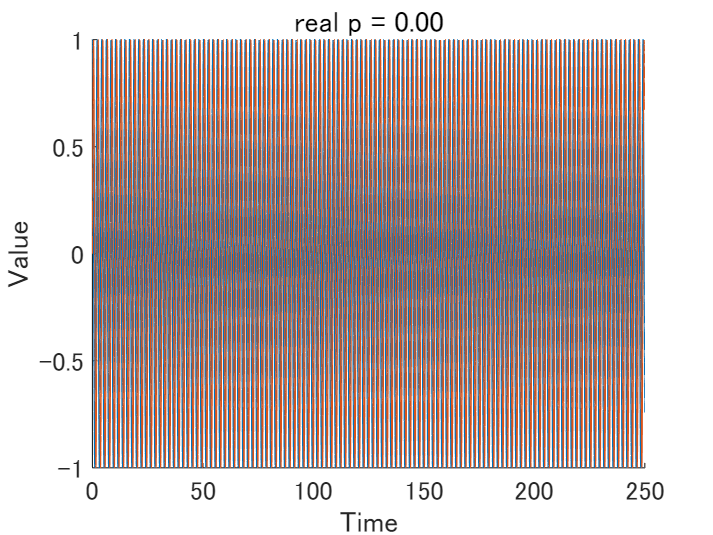

    0.9086



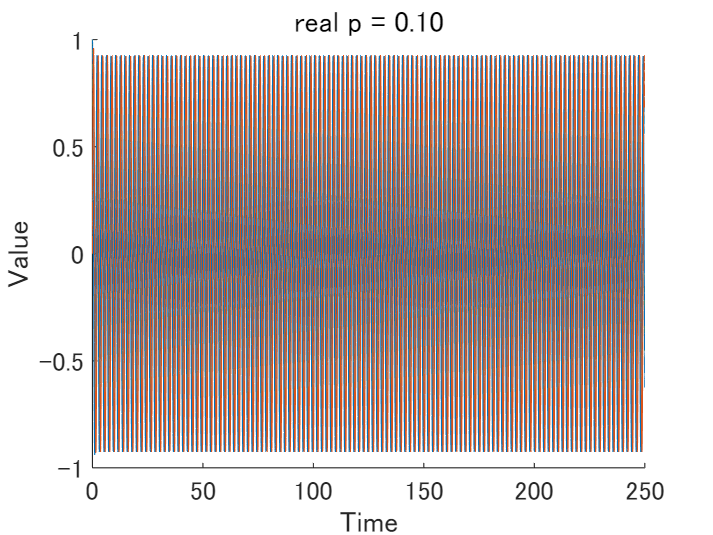

    0.8079



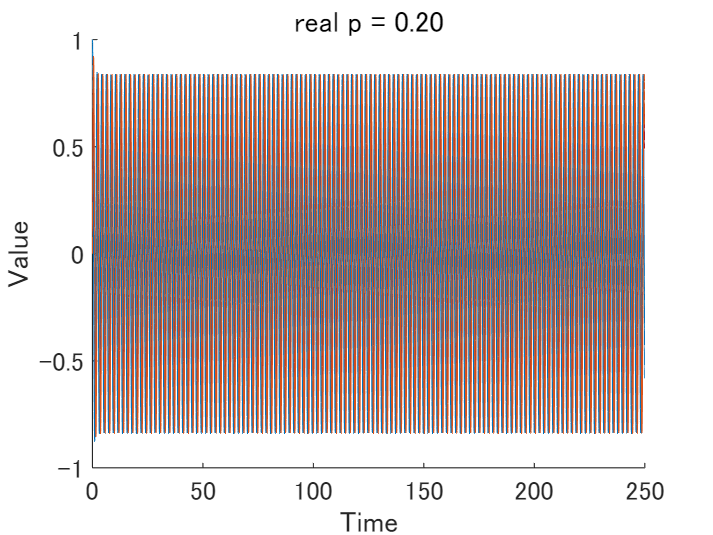

    0.6899



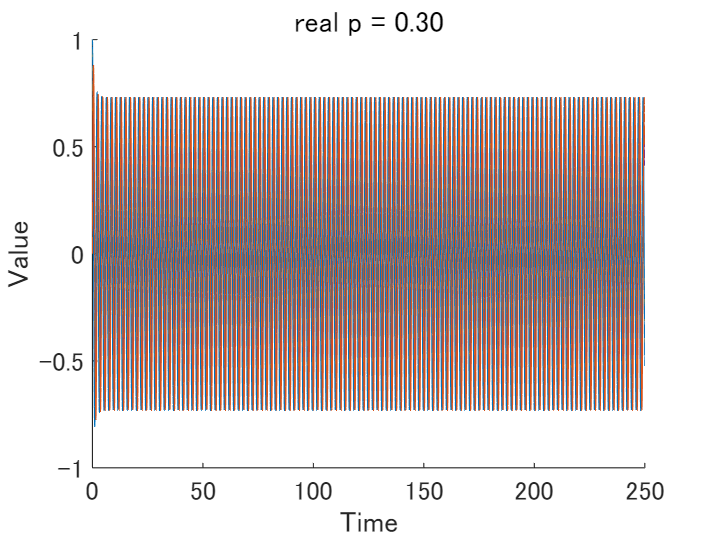

    0.5451



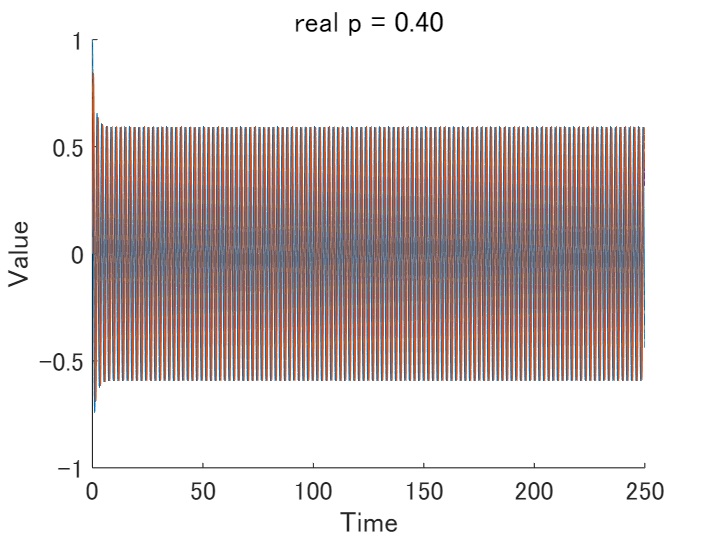

    0.3396



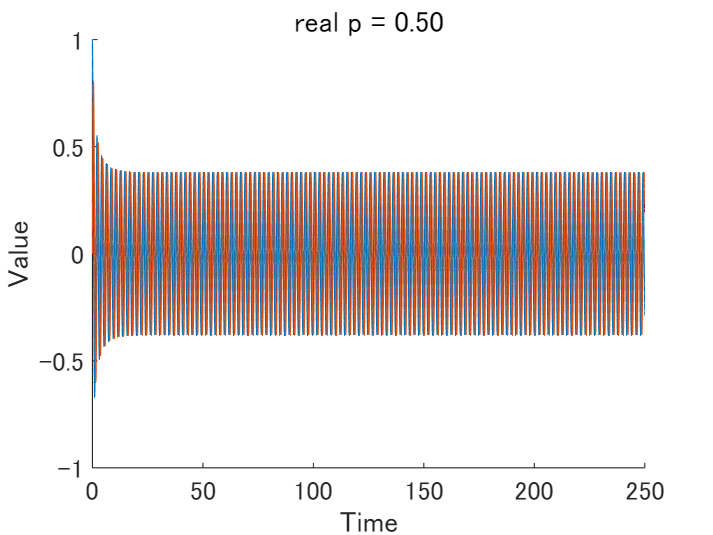

   5.7506e-09



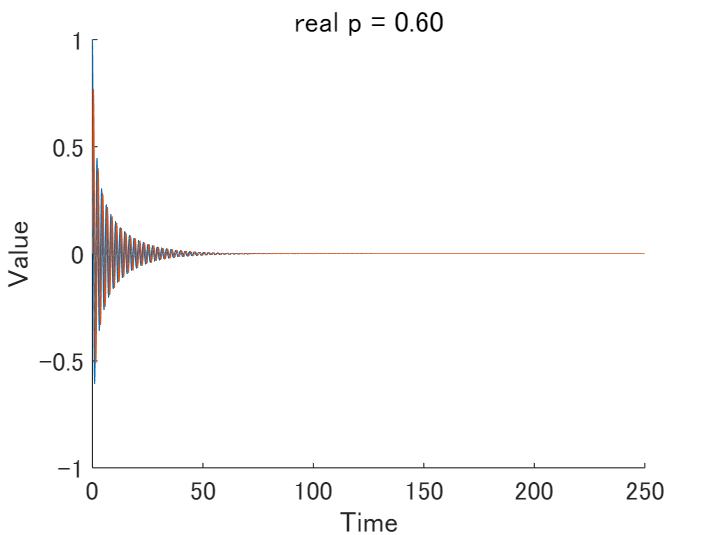

   3.3155e-08



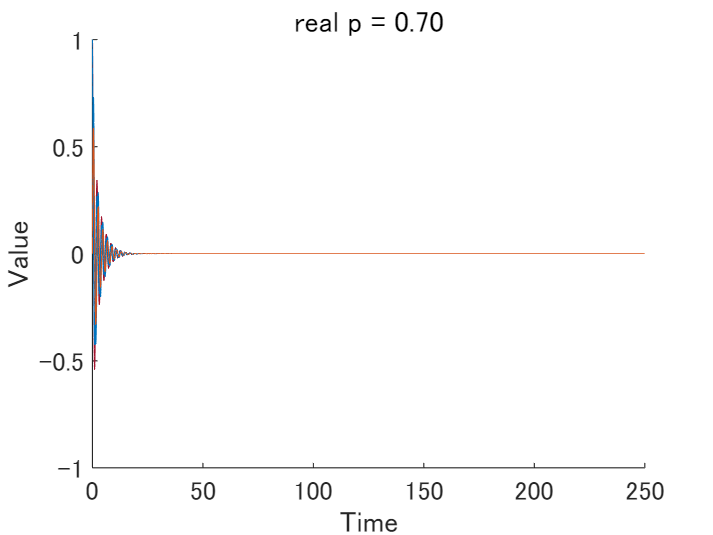

   1.1626e-07



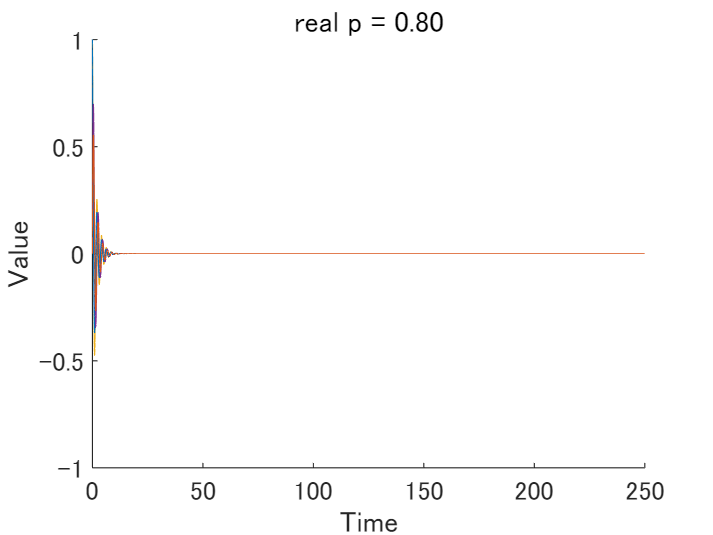

   1.4552e-08



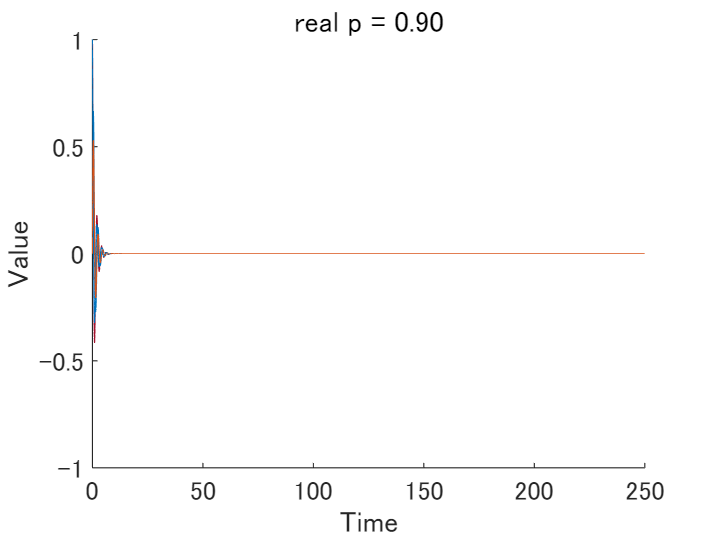

   1.9794e-07



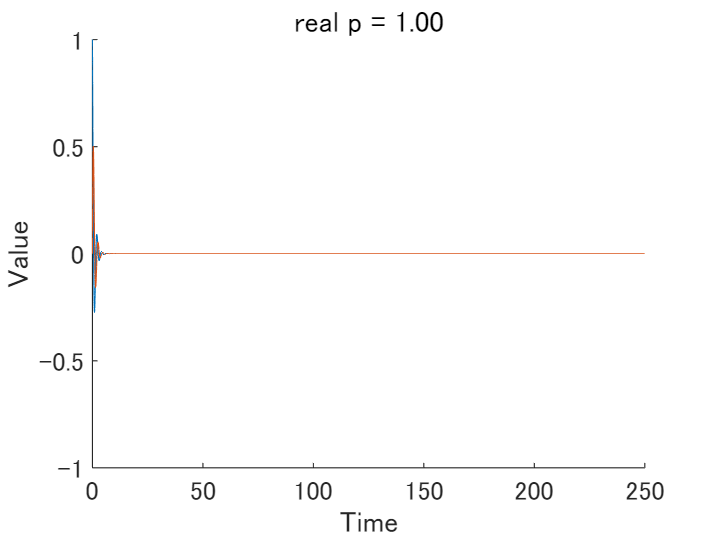

% 時間ベクトル（横軸）
time = t(ntrans + 1:end); % 過渡期以降の時間

for p = 0:0.1:1
    z_data = solve_model(t_steps, ntrans, dim, t, p, numNodes, ...
    coefficientOfActiveNodes, coefficientOfInactiveNodes, z_initial, omega, dencityBetweenNodes, adjacencyMatrix);

    % 実部と虚部を取り出して複素数に戻す
    real_part = z_data(:, 1:2:end); % 偶数番目が実部
    imag_part = z_data(:, 2:2:end); % 奇数番目が虚部  
   
    % 複素数形式に再構築
    z_data_merge = real_part + 1i * imag_part;

    % 振幅の平均を計算
    A = abs(z_data_merge);
    z_amplitude = mean(A, 2);
    disp(z_amplitude(end));
    odd_rows = z_data(:, 1:2:end);
    
    % プロット
    figure;
    hold on;

    for i = 1:numNodes
        plot(time, odd_rows(:, i)); % 各奇数行をプロット
    end
    hold off;

    % グラフの装飾
    p_str = sprintf('%.2f', p); 
    title(sprintf('real p = %s', p_str),'FontSize', 16);
    xlabel('Time', 'FontSize', 14);
    ylabel('Value', 'FontSize', 14);
    ylim([-1 1]);
    %xlim([30 60]);
    set(gca, 'FontSize', 12);
end